# ADCS Homework 4

## Problem 1

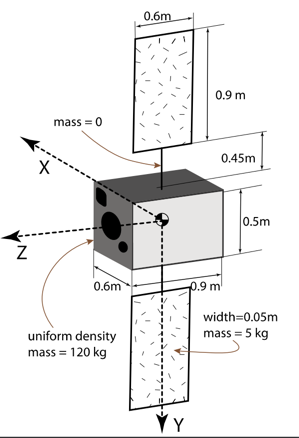

### Assumptions:

1. The thickness of the panels goes into the +x direction. 

2. Origin is at (0,0,0) and each vector points to the geometric center of each rectangular prism.

3. Solar Panel 1 is in the +y direction

### (A) Find the Center of Mass Coordinates

% Vectors to each geometric center (GC)
origin_to_busGC = [0.5*0.6; 0.5*0.5; 0.5*0.9] % meters

origin_to_busGC =     0.3000
    0.2500
    0.4500


origin_to_SP1GC = [0.5*0.005; 0.5*0.9 + 0.45; 0.5*0.6] % meters

origin_to_SP1GC =     0.0025
    0.9000
    0.3000


origin_to_SP2GC = [0.5*0.005; -1*(0.5*0.9 + 0.45); 0.5*0.6] % meters

origin_to_SP2GC =     0.0025
   -0.9000
    0.3000



busMass = 120 % kg

busMass = 120

SPMass = 5 % kg

SPMass = 5

totalMass = busMass + 2*SPMass

totalMass = 130


CM_Coordinates = (1/totalMass)*(busMass*origin_to_busGC + ...
                    SPMass*origin_to_SP1GC + SPMass*origin_to_SP2GC)

CM_Coordinates =     0.2771
    0.2308
    0.4385


### (B) Find the Inertia Tensor relative to the CM

% CM to Geometric Centers
r_cmToBus = origin_to_busGC - CM_Coordinates;
r_cmToSP1 = origin_to_SP1GC - CM_Coordinates;
r_cmToSP2 = origin_to_SP2GC - CM_Coordinates;

% Diagonal Tensor Elements
Ixx = (busMass*(r_cmToBus(2)^2 + r_cmToBus(3)^2)) + ...
    (SPMass*(r_cmToSP1(2)^2+r_cmToSP1(3)^2)) + ...
    (SPMass*(r_cmToSP2(2)^2 + r_cmToSP2(3)^2))

Ixx = 8.8846

Iyy = (busMass*(r_cmToBus(1)^2 + r_cmToBus(3)^2)) + ...
    (SPMass*(r_cmToSP1(1)^2+r_cmToSP1(3)^2)) + ...
    (SPMass*(r_cmToSP2(1)^2 + r_cmToSP2(3)^2))

Iyy = 1.0247

Izz = (busMass*(r_cmToBus(2)^2 + r_cmToBus(1)^2)) + ...
    (SPMass*(r_cmToSP1(2)^2+r_cmToSP1(1)^2)) + ...
    (SPMass*(r_cmToSP2(2)^2 + r_cmToSP2(1)^2))

Izz = 9.4939


% Off Diagonals
Ixy = (-1)*((busMass*(r_cmToBus(1)*r_cmToBus(2))) + ...
    (SPMass*(r_cmToSP1(1)*r_cmToSP1(2))) + ...
    (SPMass*(r_cmToSP2(1)*r_cmToSP2(2))))

Ixy = -0.6865

Iyx = Ixy

Iyx = -0.6865

Iyz = (-1)*((busMass*(r_cmToBus(2)*r_cmToBus(3))) + ...
    (SPMass*(r_cmToSP1(2)*r_cmToSP1(3))) + ...
    (SPMass*(r_cmToSP2(2)*r_cmToSP2(3))))

Iyz = -0.3462

Izy = Iyz

Izy = -0.3462

Ixz = (-1)*((busMass*(r_cmToBus(1)*r_cmToBus(3))) + ...
    (SPMass*(r_cmToSP1(1)*r_cmToSP1(3))) + ...
    (SPMass*(r_cmToSP2(1)*r_cmToSP2(3))))

Ixz = -0.4119

Izx = Ixz 

Izx = -0.4119


I = [Ixx Ixy Ixz; Iyx Iyy Iyz; Izx Izy Izz]

I =     8.8846   -0.6865   -0.4119
   -0.6865    1.0247   -0.3462
   -0.4119   -0.3462    9.4939


## Problem 2

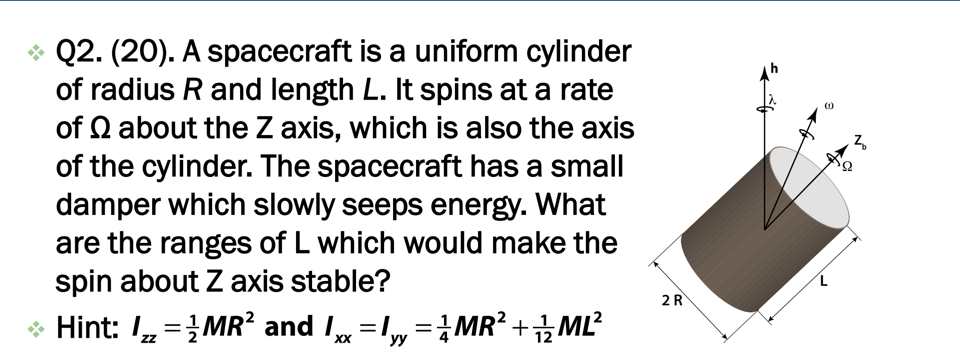

Since we are spinning about the Z-axis, we need the following conditions to hold:

$I_z > Ix$ and $I_z > I_y$

or

$I_z < I_x$ and $I_z < I_y$

Since $I_{xx} = I_{yy}$, we have basically two inequalities instead of four.

1. $I_z > I_x$


$$\frac{1}{2} M R^2 > \frac{1}{4}MR^2 + \frac{1}{12}ML^2$$



$$R^2 > \frac{1}{3}L^2$$



$$|R| > \frac{1}{\sqrt{3}} L$$


2. $I_z < I_x$


$$\frac{1}{2} MR^2 < \frac{1}{4}MR^2 + \frac{1}{12}ML^2$$



$$3R^2 < L^2$$



$$\sqrt{3}R < |L|$$


## Problem 3

### The dimensions in the satellite above are $R = 1.0$m, $L = 2.0$m, $M = 150$kg, $\Omega = 5.0$rpm.

### (a) What is the nutation Frequency?

The formula for the nutation frequency is


$$\lambda = \Omega \frac{I_z - Ix}{I_x}$$


R = 1.0 % m

R = 1

L = 2.0 % m

L = 2

M = 150 % kg

M = 150

Omega = 5.0 * (2*pi)*(1/60) % rad/s

Omega = 0.5236

Iz = (1/2)*M*R^2

Iz = 75

Ix = (1/4)*M*R^2 + (1/12)*M*L^2

Ix = 87.5000

Lambda = Omega*(Iz - Ix)/Ix

Lambda = -0.0748

### (b) If the nutation angle is $10^{\circ$, what are the angular rates, the total momentum, and the total kinetic energy?

The formulas needed are


$$\tan(\theta) = \frac{I_x \omega_{xy}}{I_z \omega_z}$$



$$\tan(\gamma) = \frac{\omega_{xy}}{\omega_z}$$



$$\tan(\theta) = \frac{I_x}{I_z} \tan(\gamma)$$



$$h^2 = \omega_{xy}^{2} I_x^2 + \omega_z^2 I_z^2$$



$$2T = \omega_{xy}^2 I_x + \omega_z^2 I_z$$


theta = 10 * (pi/180) % rad

theta = 0.1745

gamma = atan(Iz * tan(theta)/Ix)

gamma = 0.1500

If $\omega_z = \Omega$, we can find $\omega_{xy}$

omega_xy = Omega*tan(gamma)

omega_xy = 0.0791

h = sqrt(omega_xy^2 * Ix^2 + Omega^2*Iz^2)

h = 39.8757

T = (1/2)*(omega_xy^2 * Ix + Omega * Iz)

T = 19.9089

### (c) What is the lowest energy level? What is the nutation angle at this point?

If the kinetic energy has setlled into the lowest energy level, then $\dot{T} = 0$. From here, we can see that 


$$\cos(\theta) \sin(\theta) = 0$$



$$\sin(2\theta)=0$$



$$\theta = \frac{\pi}{4}$$


Using the nutation angle formula for $T$,


$$T = \frac{1}{2I_x}\left(h^2 - h^2 \cos^2(\theta)\frac{I_z - I_x}{I_z}\right)$$


we get

theta_new = pi/4

theta_new = 0.7854

T = (1/(2*Ix))*(h^2 - h^2*(cos(theta_new))^2*((Iz - Ix)/Iz))

T = 9.8433